# `SnailTrailChart`** Examples**

**Overview**

The `SnailTrailChart` visualizes the evolution of the relative performance of an asset over time. The chart data (`Returns`) comprises a timetable with row times and variables as follows:

- `Date` - the row times of the timetable - an increasing `datetime` vector corresponding to the benchmark and asset returns;

- `Benchmark` - a numeric vector containing the return series for the performance benchmark (for example, the performance benchmark could be the returns of the FTSE100 or S&P500 indices, or another reference portfolio);

- `Asset` - a numeric vector containing the return series for the asset of interest (for example, a portfolio).

From the chart data, the following performance metrics are computed in rolling windows:

- Excess return - the mean of the difference between the asset and the benchmark returns;

- Tracking error - the standard deviation of the difference between the asset and the benchmark returns;

- Information ratio - the ratio of the excess return to the tracking error.

The chart creates a scatter graph of excess return against tracking error, colored by information ratio. The reference lines $x=0$ and $y=0$ are highlighted to separate the two quadrants for which $x>0$. The snail trail is plotted over the scatter graph, and comprises a head and a trail. A text box displays the performance statistics corresponding to the position of the head.

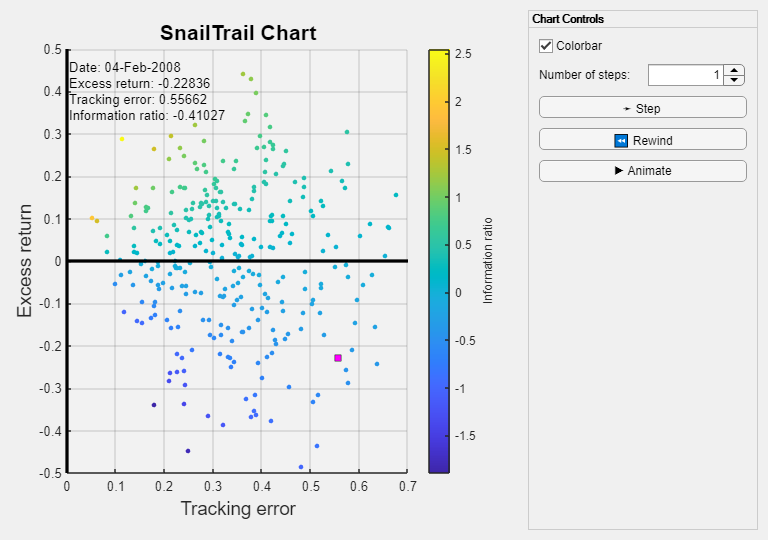

The `Period` property of the chart specifies the window length (that is, the number of observations used in each rolling window). The head of the trail is set using either the `CurrentIndex` (an integer) or `CurrentDate` (a `datetime`) chart properties. The length of the trail is controlled by modifying the `TrailLength` property. To move the snail trail around the chart, use the `step`, `animate` and `reset` methods.

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "SnailTrail.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "SnailTrail.m"))) the source code for the `SnailTrailChart`.

## Load the data.

load( fullfile( chartsDocRoot(), "data", "Returns.mat" ), "rets" )

## Create a figure for the chart.

f = exampleFigure( "Name", "SnailTrailChart Example" );

## Create the chart.

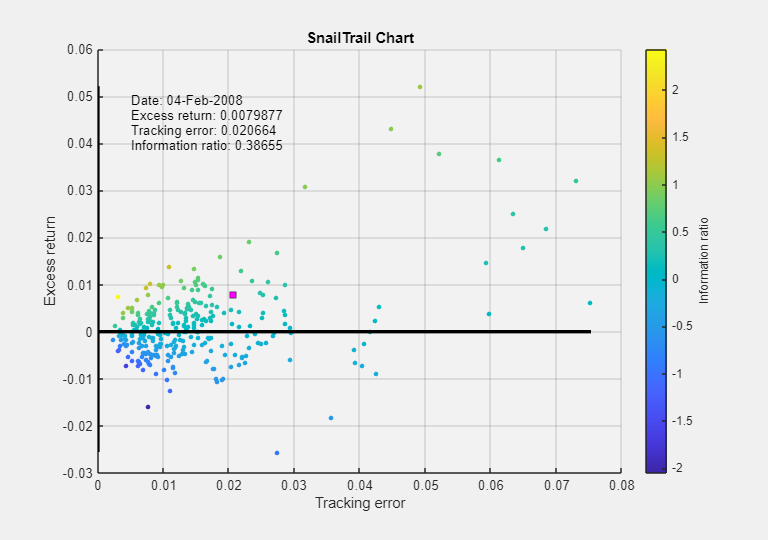

STC = SnailTrailChart( "Parent", f, ...
    "Returns", rets );

## Customize the chart appearance.

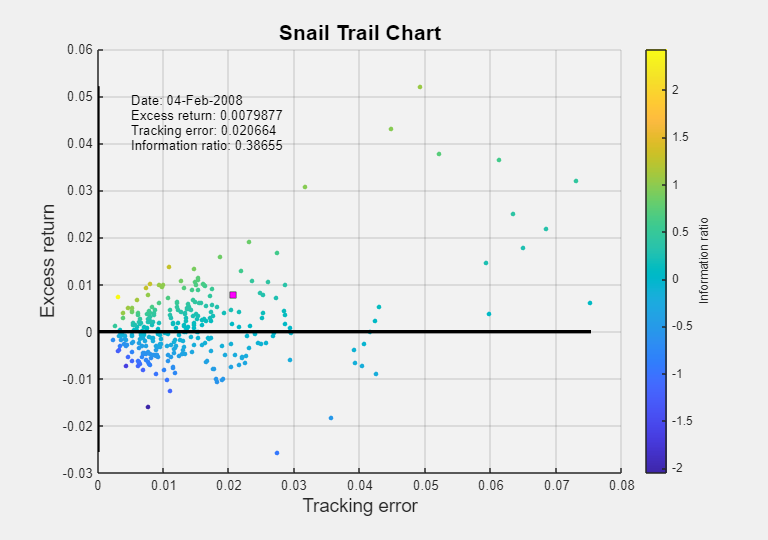

xlabel( STC, "Tracking error", "FontSize", 14 )
ylabel( STC, "Excess return", "FontSize", 14 )
title( STC, "Snail Trail Chart", "FontSize", 16 )

## Step the trail.

numSteps = 20;
step( STC, numSteps )

Adjust the trail length.

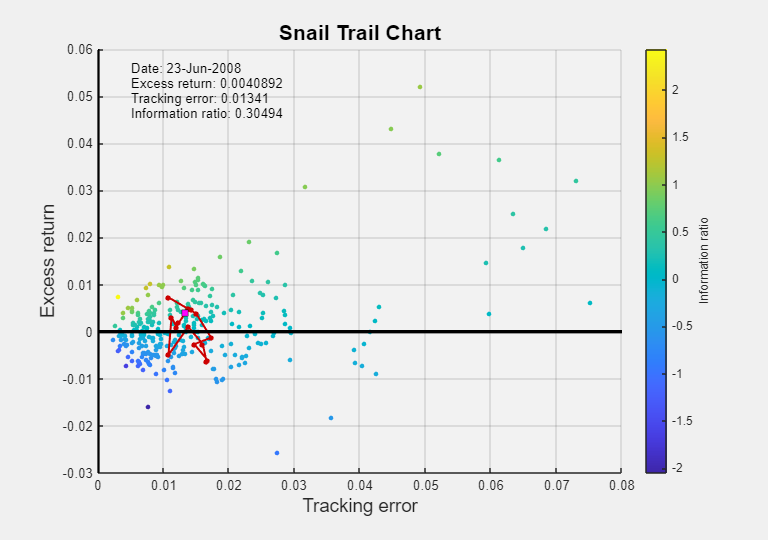

STC.TrailLength = 15;

## Update the chart data.

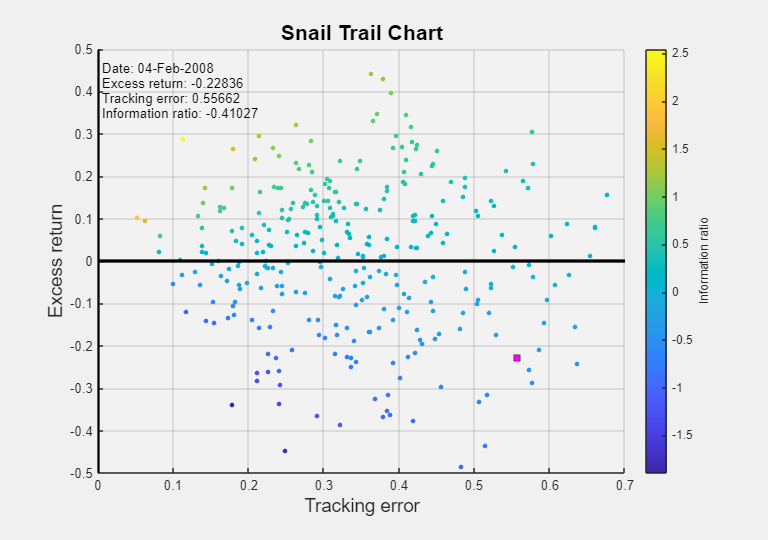

rng( "default" )
sampleRets = 0.25 * randn( height( rets ), 2 );
sampleRets = array2timetable( sampleRets, "RowTimes", rets.Date );
STC.Returns = sampleRets;

*Copyright 2018-2025 The MathWorks, Inc.*